CREDITS

Made by Rahul S. Yerrabelli under Nai-Kong Cheung, MD, PhD at Memorial Sloan Kettering Cancer Center This is part of the code accompanying the publication of "Intra-Ommaya Compartmental Radioimmunotherapy using 131I-Omburtamab— Pharmacokinetic Modeling to Optimize Therapeutic Index" in European Journal of Nuclear Medicine and Molecular Imaging (EJNMMI) (Accepted Sep 19, 2020). See that paper and its supplement file for a greater description of the model and results.

Get basic values defined and then solve the model for a range of activities and administration times.

Simulations.DefaultValues;
defined_params = [immunoreactivity, tumorload, perTV, perNB, ...
    kAR, k_AR, V, n, MM, cI0, t_half];

treatment_cts = [1:6 8]; %how many splits should you do? Each element in the vector will be one situation that will be calculated.
%treatment_cts = [1:8]; 
%treatment_cts = [1 2 3];

co=get(gca,'ColorOrder');
%cols = co([5 6 7 4 3 2 1],:);
cols = co([1:7], :);


**Make the tables using fminsearch **(should be more precise than getting it from graphed values, although this was not true for TP time numbers)

First, find the optimized values of the AUC_cIAR and therapeutic product (we know only these two have maxes because of plotting the rest first originally) so they're definitely included in the plot

%Single Injection values to compare
[t1, cIobs1, AUC_cIAR1, AUC_cIA1, ~] = solveModelMultInfus(0,activityAdmin,...
    Vv, CL, [0:1:(4*1440)]*60, defined_params);
theraprat1 = AUC_cIAR1/AUC_cIA1;
therapprod1 = (AUC_cIAR1^2/AUC_cIA1);
%range of days to search for the max (inputting to fminbnd function)
min_search_bound = 0; %days
max_search_bound = 28; %days, 14 is enough for max value, but need to go higher to get the 1.1x value
bound_range = 0.2; %find times that have values within this range of the max (0.2 -> between 90-110% of max improvement; Note, this is of the improvement number, not the absolute or the relative % number)



Maximize AUC[C_IAR]

opt_val = 1; %1->what to optimize: AUC_cIAR, 2->AUC_cIA, 3->TI, 4->TI*AUC_cIAR
%3D matrix. First dim is inj cts. 2nd dim has max time t, max AUCcIAR, cI@t, rat@t, prod@t. 3rd dim organizes by values for 90% mark, the max mark, and the 110% mark
optim_AUC_cIAR = NaN(length(treatment_cts),5,3);

Undefined function or variable 'treatment_cts'.

optim_AUC_cIAR(treatment_cts==1,:,2) = [NaN,AUC_cIAR1,AUC_cIA1,theraprat1,therapprod1]; %set values for 1 single injction
for it = 2:length(treatment_cts)
    treatment_ct = treatment_cts(it);
    %maximize solveWithSchedule by minimizing the negative
    maxTime = fminbnd(@(tm) -solveWithSchedule(treatment_ct,opt_val,tm,...
        activityAdmin,Vv,CL, defined_params), min_search_bound, max_search_bound);
    [~,AUC_cIAR_opt, AUC_cIA_opt, therapind_opt, therapprod_opt] = ...
        solveWithSchedule(treatment_ct,opt_val,maxTime, activityAdmin,Vv,CL, defined_params);
    optim_AUC_cIAR(it,:,2)=[maxTime,AUC_cIAR_opt,AUC_cIA_opt,therapind_opt,therapprod_opt];
    optim_delay = maxTime/(treatment_ct-1);
    disp(['For ' num2str(treatment_ct) ' injections, optimal AUC[C_IAR]''s total time = '...
        num2str(maxTime) ' days aka ' num2str(optim_delay)...
        ' day (' num2str(optim_delay*24) 'hr; ' num2str(floor(optim_delay*24)) 'hr ' num2str(mod(optim_delay*24,1)*60) 'min) delay between injections => ' num2str(100*AUC_cIAR_opt/AUC_cIAR1,5) '%']);
    
    %Find the range of values
    if max_search_bound > 20 %days, otherwise will give error because can't find the 110% mark
        %Need to find the times first, then calculate the rest because otherwise AUC_cIAR_opt will be overwritten
        maxTimeStartBorder = fzero( @(tm) (solveWithSchedule(treatment_ct,opt_val,tm,...
            activityAdmin,Vv,CL, defined_params)-AUC_cIAR1 - (AUC_cIAR_opt-AUC_cIAR1)*(1-bound_range/2)), [min_search_bound maxTime] );
        maxTimeEndBorder = fzero( @(tm) (solveWithSchedule(treatment_ct,opt_val,tm,...
            activityAdmin,Vv,CL, defined_params)-AUC_cIAR1 - (AUC_cIAR_opt-AUC_cIAR1)*(1-bound_range/2)), [maxTime max_search_bound] );
        [~,AUC_cIAR_opt, AUC_cIA_opt, therapind_opt, therapprod_opt] = ...
            solveWithSchedule(treatment_ct,opt_val,maxTimeStartBorder, activityAdmin,Vv,CL, defined_params);
        optim_AUC_cIAR(it,:,1)=[maxTimeStartBorder,AUC_cIAR_opt,AUC_cIA_opt,therapind_opt,therapprod_opt];
        [~,AUC_cIAR_opt, AUC_cIA_opt, therapind_opt, therapprod_opt] = ...
            solveWithSchedule(treatment_ct,opt_val,maxTimeEndBorder, activityAdmin,Vv,CL, defined_params);
        optim_AUC_cIAR(it,:,3)=[maxTimeEndBorder,AUC_cIAR_opt,AUC_cIA_opt,therapind_opt,therapprod_opt];
    end
end


Maximize therapeutic product (TI*AUC[C_IAR])

Note- the time values ended not being reliable for fminsearch bc it was too flat

opt_val = 4; %1->what to optimize: AUC_cIAR, 2->AUC_cIA, 3->TI, 4->TI*AUC_cIAR
%3D matrix. First dim is inj cts. 2nd dim has max time t, max AUCcIAR, cI@t, rat@t, prod@t. 3rd dim organizes by values for 90% mark, the max mark, and the 110% mark
optim_TP = NaN(length(treatment_cts), 5, 3);
optim_TP(treatment_cts==1,:,2) = [NaN,AUC_cIAR1,AUC_cIA1,theraprat1,therapprod1]; %set values for 1 single injection
for it = 2:length(treatment_cts)
    treatment_ct = treatment_cts(it);
    %maximize solveWithSchedule by minimizing the negative
    maxTime = fminbnd(@(tm) -solveWithSchedule(treatment_ct,opt_val,tm,...
        activityAdmin,Vv,CL, defined_params), min_search_bound, max_search_bound);
    [~,AUC_cIAR_opt, AUC_cIA_opt, therapind_opt, therapprod_opt] = ...
        solveWithSchedule(treatment_ct,opt_val,maxTime, activityAdmin,Vv,CL, defined_params);

    %NOTE. THE FMINBND DERIVED NUMBERS WERE NOT THAT PRECISE FOR TP (WERE GOOD FOR TR). They gave the write max, but not the exact best time since the peak was pretty broad. Instead use the graph max.
    optim_TP(it,:,2)=[maxTime,AUC_cIAR_opt,AUC_cIA_opt,therapind_opt,therapprod_opt];
    optim_delay = maxTime/(treatment_ct-1);
    disp(['For ' num2str(treatment_ct) ' injections, optimal product''s total time = '...
        num2str(maxTime) ' days aka ' num2str(optim_delay)...
        ' day (' num2str(optim_delay*24) 'hr; ' num2str(floor(optim_delay*24)) 'hr ' num2str(mod(optim_delay*24,1)*60) 'min) delay between injections =>' num2str(100*AUC_cIAR_opt/AUC_cIAR1,5) '% x ' num2str(100*therapind_opt/theraprat1,5) '% = ' num2str(100*therapprod_opt/therapprod1,5) '%']);

    
    %Find the range of values
    if max_search_bound > 20 %days, otherwise will give error because can't find the 110% mark
        %Need to find the times first, then calculate the rest because otherwise therapprod_opt will be overwritten
        maxTimeStartBorder = fzero( @(tm) (solveWithSchedule(treatment_ct,opt_val,tm,...
            activityAdmin,Vv,CL, defined_params)-therapprod1 - (therapprod_opt-therapprod1)*(1-bound_range/2)),...
            [min_search_bound maxTime], optimset('TolFun',1e-8) );
        maxTimeEndBorder = fzero( @(tm) (solveWithSchedule(treatment_ct,opt_val,tm,...
            activityAdmin,Vv,CL, defined_params)-therapprod1 - (therapprod_opt-therapprod1)*(1-bound_range/2)),...
            [maxTime max_search_bound] );
        [~,AUC_cIAR_opt, AUC_cIA_opt, therapind_opt, therapprod_opt] = ...
            solveWithSchedule(treatment_ct,opt_val,maxTimeStartBorder, activityAdmin,Vv,CL, defined_params);
        optim_TP(it,:,1)=[maxTimeStartBorder,AUC_cIAR_opt,AUC_cIA_opt,therapind_opt,therapprod_opt];
        [~,AUC_cIAR_opt, AUC_cIA_opt, therapind_opt, therapprod_opt] = ...
            solveWithSchedule(treatment_ct,opt_val,maxTimeEndBorder, activityAdmin,Vv,CL, defined_params);
        optim_TP(it,:,3)=[maxTimeEndBorder,AUC_cIAR_opt,AUC_cIA_opt,therapind_opt,therapprod_opt];
    end
end

For 2 injections, optimal product's total time = 3.6125 days aka 3.6125 day (86.7007hr; 86hr 42.0432min) delay between injections =>127.95% x 137.89% = 176.43%


For 3 injections, optimal product's total time = 4.549 days aka 2.2745 day (54.5878hr; 54hr 35.2677min) delay between injections =>140.35% x 159% = 223.17%


For 4 injections, optimal product's total time = 5.5695 days aka 1.8565 day (44.5557hr; 44hr 33.3407min) delay between injections =>145.84% x 173.04% = 252.36%


For 5 injections, optimal product's total time = 6.1389 days aka 1.5347 day (36.8337hr; 36hr 50.0208min) delay between injections =>149% x 182.08% = 271.3%


For 6 injections, optimal product's total time = 6.5208 days aka 1.3042 day (31.3hr; 31hr 18.0016min) delay between injections =>150.83% x 188.21% = 283.87%


For 7 injections, optimal product's total time = 6.7521 days aka 1.1254 day (27.0085hr; 27hr 0.5115min) delay between injections =>151.96% x 192.33% = 292.25%


For 8 injections, optimal product's total time = 7.3037 days aka 1.0434 day (25.0413hr; 25hr 2.4805min) delay between injections =>151.66% x 196.45% = 297.94%


Display data on maxes

*dim=1->start bound of nearby range*

*dim=2->maximum*

*dim=3-> end bound of nearby range*



dim=2;
maximizing_AUC_cIAR_table = table(treatment_cts', optim_AUC_cIAR(:,1,dim), optim_AUC_cIAR(:,1,dim)./(treatment_cts-1)'*24, optim_AUC_cIAR(:,2,dim)/AUC_cIAR1*100, optim_AUC_cIAR(:,4,dim)/theraprat1*100, optim_AUC_cIAR(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

maximizing_AUC_cIAR_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1          NaN          NaN            100         100       100
    2       3.0042       72.101         128.43      136.73    175.61
    3       3.7469       44.962         141.19      156.53       221
    4       4.2806       34.245         147.64      168.65    249.01
    5       4.6691       28.015         151.11      176.26    266.34
    6       4.9509       23.764         153.02      181.37    277.52
    7       5.1536       20.614         154.07      184.77    284.66
    8       5.2973       18.162         154.63      187.15     289.4


dim=1;
start_border_AUC_cIAR_table = table(treatment_cts', optim_AUC_cIAR(:,1,dim), optim_AUC_cIAR(:,1,dim)./(treatment_cts-1)'*24, optim_AUC_cIAR(:,2,dim)/AUC_cIAR1*100, optim_AUC_cIAR(:,4,dim)/theraprat1*100, optim_AUC_cIAR(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

start_border_AUC_cIAR_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1          NaN          NaN            NaN         NaN       NaN
    2       1.9468       46.723         125.59      130.79    164.26
    3       2.4184       29.021         137.07      146.59    200.93
    4       2.7408       21.926         142.88      155.71    222.48
    5       2.9616        17.77            146      161.12    235.24
    6       3.1114       14.935         147.71      164.58    243.11
    7       3.2115       12.846         148.66      166.75    247.89
    8        3.277       11.236         149.17      168.14    250.82


dim=3;
end_border_AUC_cIAR_table = table(treatment_cts', optim_AUC_cIAR(:,1,dim), optim_AUC_cIAR(:,1,dim)./(treatment_cts-1)'*24, optim_AUC_cIAR(:,2,dim)/AUC_cIAR1*100, optim_AUC_cIAR(:,4,dim)/theraprat1*100, optim_AUC_cIAR(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

end_border_AUC_cIAR_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1          NaN          NaN            NaN         NaN       NaN
    2       4.8334          116         125.59      138.62    174.09
    3       5.8462       70.154         137.07      160.59    220.12
    4       6.5987       52.789         142.88      174.57    249.42
    5       7.1674       43.004            146      184.01    268.65
    6       7.5994       36.477         147.71      190.61    281.56
    7        7.927       31.708         148.66      195.39    290.46
    8       8.1741       28.025         149.17      198.87    296.65




dim=2;
maximizing_TP_table = table(treatment_cts', optim_TP(:,1,dim), optim_TP(:,1,dim)./(treatment_cts-1)'*24, optim_TP(:,2,dim)/AUC_cIAR1*100, optim_TP(:,4,dim)/theraprat1*100, optim_TP(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

maximizing_TP_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1          NaN          NaN            100         100       100
    2       3.6125       86.701         127.95      137.89    176.43
    3        4.549       54.588         140.35         159    223.17
    4       5.5695       44.556         145.84      173.04    252.36
    5       6.1389       36.834            149      182.08     271.3
    6       6.5208         31.3         150.83      188.21    283.87
    7       6.7521       27.009         151.96      192.33    292.25
    8       7.3037       25.041         151.66      196.45    297.94


dim=1;
start_border_TP_table = table(treatment_cts', optim_TP(:,1,dim), optim_TP(:,1,dim)./(treatment_cts-1)'*24, optim_TP(:,2,dim)/AUC_cIAR1*100, optim_TP(:,4,dim)/theraprat1*100, optim_TP(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

start_border_TP_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1          NaN          NaN            NaN         NaN       NaN
    2       2.2069       52.967         126.97      132.92    168.76
    3       2.8604       34.325         139.56      151.04    210.79
    4       3.3556       26.844         146.14      162.19    237.02
    5       3.7431       22.458         149.81      169.74    254.29
    6       4.0458        19.42         151.92      174.82     265.6
    7       4.2778       17.111         153.15      178.37    273.17
    8       4.4556       15.276         153.85      180.69    277.98


dim=3;
end_border_TP_table = table(treatment_cts', optim_TP(:,1,dim), optim_TP(:,1,dim)./(treatment_cts-1)'*24, optim_TP(:,2,dim)/AUC_cIAR1*100, optim_TP(:,4,dim)/theraprat1*100, optim_TP(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

end_border_TP_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1          NaN          NaN            NaN         NaN       NaN
    2       6.5634       157.52         121.68      138.72    168.78
    3       7.8525        94.23         130.83      161.16    210.85
    4       8.9105       71.284         134.91      175.77    237.12
    5       9.7922       58.753         136.61      186.06    254.17
    6       10.526       50.523         137.15      193.56    265.48
    7       11.153       44.612         137.06      199.21    273.03
    8       11.702       40.121         136.59      203.64    278.14


Note: The start border TP values often weren't exactly 90%. I used the values anyway, but kept the 90% TP cutoff (which coincided with the end border TP) values on the manuscript

Proof that the max_search_bound affects the max time for therapeutic product (but not AUC[C_IAR] and not the actual TP value) because fminsearch cannot handle the flatness of the TP curve

TP

max_search_bounds = 7:0.5:28;
outputs_by_bound = NaN(size(max_search_bounds));
opt_val = 4;
for it = 1:length(max_search_bounds)
    outputs_by_bound(it) = fminbnd(@(tm) -solveWithSchedule(2,opt_val,tm,...
        activityAdmin,Vv,CL, defined_params), min_search_bound, max_search_bounds(it));
end

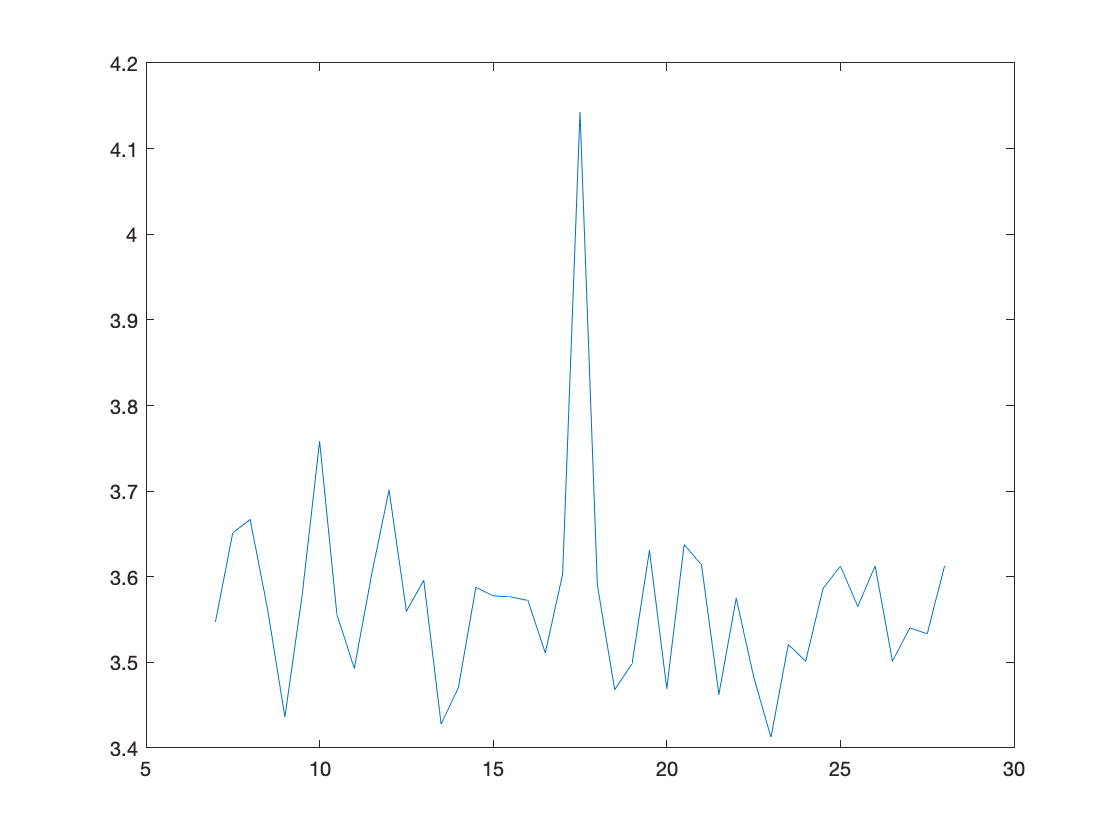

figure;
plot(max_search_bounds,outputs_by_bound);

AUC[C_IAR]

max_search_bounds = 7:0.5:28;
check_times = [2 3.6 5 6.5];
outputs_by_bound = NaN(length(max_search_bounds),length(check_times));
opt_val = 4;
for it = 1:length(max_search_bounds)
    for it2 = 1:length(check_times)
        outputs_by_bound(it,it2) = solveWithSchedule(2,opt_val,check_times(it2),...
            activityAdmin,Vv,CL, defined_params);
    end
end

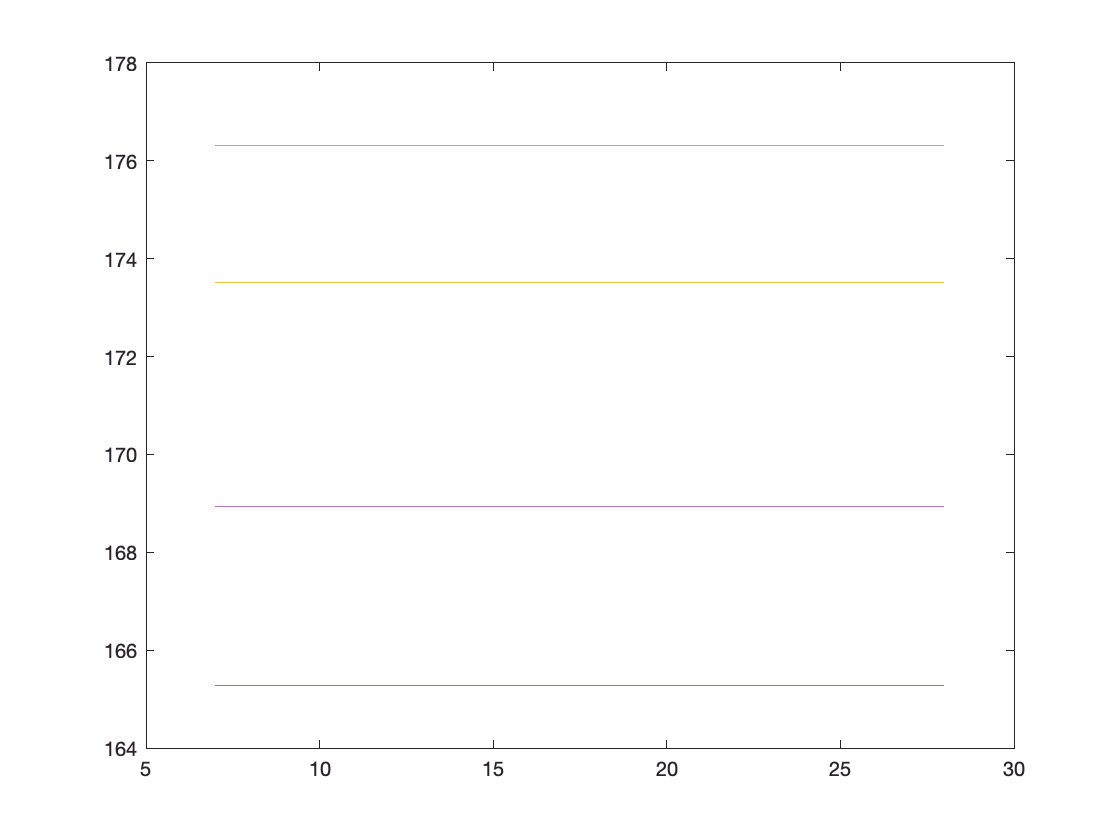

figure;
%plot(max_search_bounds,outputs_by_bound/AUC_cIAR1*100);
plot(max_search_bounds,outputs_by_bound/therapprod1*100);

**Get Data to Plot**

treatment_times = [.125/2 .125 .25:.25:7 8:14 ];%[12 24 48 72 96 24*7]; %hrs
%treatment_times = linspace(0.05,14); %changing the max value changes the peak times for some reason
treatment_times = 0.04:0.01:14; %changing the max value changes the peak times for some reason
%treatment_times = sort([treatment_times 3:0.02:7.3]);
%treatment_times = sort([treatment_times optim_AUC_cIAR(:,1)' optim_TP(:,1)']);

Load simulation data if it was already done before (saves time)

load(['+Simulations/Scheduling/data_for_injections=(' num2str(treatment_cts) ')_and_' num2str(length(treatment_times)) '_times_up_to=' num2str(treatment_times(end)) '.mat'])

Calculate Data

[trt_cts_grid, trt_times_grid] = meshgrid(treatment_cts, treatment_times);
ys = NaN([size(trt_cts_grid) 4]);
[t1, cIobs1, AUC_cIAR1, AUC_cIA1, ~] = solveModelMultInfus(0,activityAdmin,...
    Vv, CL, [0:1:(4*1440)]*60, defined_params);
theraprat1 = AUC_cIAR1/AUC_cIA1;
therapprod1 = (AUC_cIAR1^2/AUC_cIA1);

%the treatment time = time from first injection to last injection
for it = 1:length(treatment_times)
    ys(it, 1, :) = [AUC_cIAR1 AUC_cIA1 theraprat1 therapprod1]; %single injection
    for ict = 2:length(treatment_cts)
        treatment_ct = treatment_cts(ict);
        time_values_needed3 = [0:1:((treatment_times(it)+4)*1440)]*60;
        
        infusion_times = linspace(0,treatment_times(it),treatment_ct+1);
        infusion_times = infusion_times(1:end-1);
        activityAdminPerInj = activityAdmin*ones(1,treatment_ct)/treatment_ct;
        [tspl, cIobsspl, AUC_cIARspl, AUC_cIspl, alldat] = solveModelMultInfus(...
            infusion_times*3600*24, activityAdminPerInj,...
            Vv, CL, time_values_needed3, defined_params);
        ys(it,ict, :) = [AUC_cIARspl AUC_cIspl AUC_cIARspl/AUC_cIspl AUC_cIARspl*AUC_cIARspl/AUC_cIspl];
        
        %{
        %Visually see the optimal time
        figure;
        cIAR = alldat(:,5) + alldat(:,6) ;
        area(tspl/3600, cIAR); hold on;
        [pks, locs] = findpeaks(cIAR);
        text(tspl(locs)/3600, pks*1.1, strcat(num2str(pks,4),'@',num2str(tspl(locs)/3600,3)));
        plot(tspl(locs)/3600, 'o');
        [pks, locs] = findpeaks(1.01*max(cIAR)-cIAR);
        text(tspl(locs)/3600*.9, cIAR(locs)*1.1, strcat(num2str(cIAR(locs),4),'@',num2str(tspl(locs)/3600,3)));
        plot(tspl(locs)/3600, 'o');
        title([num2str(treatment_ct) ' injs over ' num2str(treatment_times(it))...
            ' days->AUC[C_{IAR}]=' num2str(trapz(tspl, cIAR),3 )]);
        ylim([0 2500]);
        %}
    end
end


Save to file for future use

save(['+Simulations/Scheduling/data_for_injections=(' num2str(treatment_cts) ')_and_' num2str(length(treatment_times)) '_times_up_to=' num2str(treatment_times(end)) '.mat'],...
    'trt_cts_grid', 'trt_times_grid', 'ys', 't1', 'cIobs1', 'AUC_cIAR1', 'AUC_cIA1','theraprat1','therapprod1');

**Get graph derived maxes** and compare with those from before from fminsearch and fzero. AUC[C_IAR] was good in fminsearch, but TP failed so need to use these numbers for TP.

AUC[C_IAR] (not necessary to do this bc should use fminsearch numbers instead, but useful for validation)

Note- remember that these are rounded to smallest subunit in the plot (0.02days as of Feb 10, 2020)

[est_maxes,est_tinds] = max(ys(:,:,1),[],1); % max of each split
%table([1:8]', treatment_times(est_tinds)',est_maxes'/AUC_cIAR1*100, 'VariableNames',{'Injs','Time_days','AUC_CIAR'})

%
optim_AUC_cIAR_est = NaN(length(treatment_cts), 5, 3);
optim_AUC_cIAR_est(treatment_cts==1,:,2) = [NaN,AUC_cIAR1,AUC_cIA1,AUC_cIAR1/AUC_cIA1, AUC_cIAR1*AUC_cIAR1/AUC_cIA1]; %set values for 1 single injection
for it = 2:length(treatment_cts)
    optim_AUC_cIAR_est(it,:,2)=[treatment_times(est_tinds(it)), reshape(ys(est_tinds(it),it,:), [1 4] ) ];
end

dim=2;
maximizing_AUC_cIAR_table = table(treatment_cts', optim_AUC_cIAR_est(:,1,dim), optim_AUC_cIAR_est(:,1,dim)./(treatment_cts-1)'*24, optim_AUC_cIAR_est(:,2,dim)/AUC_cIAR1*100, optim_AUC_cIAR_est(:,4,dim)/theraprat1*100, optim_AUC_cIAR_est(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

maximizing_AUC_cIAR_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1        NaN            NaN            100         100       100
    2          3             72         128.43      136.63    175.48
    3       3.75             45         141.19       156.5    220.96
    4       4.28          34.24         147.64      168.55    248.85
    5       4.67          28.02         151.11      176.19    266.24
    6       4.95          23.76         153.02      181.37    277.52
    7       5.15           20.6         154.07      184.75    284.64
    8        5.3         18.171         154.63      187.02    289.19


TP

Note- remember that these are rounded to smallest subunit in the plot (0.02days as of Feb 10, 2020)

[est_maxes,est_tinds] = max(ys(:,:,3).*ys(:,:,1),[],1); % max of each split
%table([1:8]', treatment_times(est_tinds)', est_maxes'/(AUC_cIAR1*AUC_cIAR1/AUC_cIA1)*100, 'VariableNames',{'Injs','Time_days','TP'})

optim_TP_est = NaN(length(treatment_cts), 5, 3);
optim_TP_est(treatment_cts==1,:,2) = [NaN,AUC_cIAR1,AUC_cIA1,AUC_cIAR1/AUC_cIA1, AUC_cIAR1*AUC_cIAR1/AUC_cIA1]; %set values for 1 single injection
for it = 2:length(treatment_cts)
    optim_TP_est(it,:,2)=[treatment_times(est_tinds(it)), reshape(ys(est_tinds(it),it,:), [1 4] ) ];
end
%table([1:8]', treatment_times(est_tinds)', est_maxes'/(AUC_cIAR1*AUC_cIAR1/AUC_cIA1)*100, 'VariableNames',{'Injs','Time_days','TP'})

dim=2;
maximizing_TP_table = table(treatment_cts', optim_TP_est(:,1,dim), optim_TP_est(:,1,dim)./(treatment_cts-1)'*24, optim_TP_est(:,2,dim)/AUC_cIAR1*100, optim_TP_est(:,4,dim)/theraprat1*100, optim_TP_est(:,5,dim)/therapprod1*100,'VariableNames',{'Injs','Time_days','Spacing_hrs','AUC_CIAR','TI','TP'})

maximizing_TP_table = 8×6 table
    Injs    Time_days    Spacing_hrs    AUC_CIAR      TI        TP  
    ____    _________    ___________    ________    ______    ______

    1        NaN            NaN            100         100       100
    2       3.55           85.2         128.03      137.81    176.44
    3       4.54          54.48         140.37      158.98    223.16
    4       5.35           42.8         146.34      172.48    252.42
    5       6.08          36.48         149.15      181.91    271.32
    6        6.6          31.68         150.63      188.41    283.79
    7       6.83          27.32         151.77      192.57    292.26
    8       7.24         24.823         151.82      196.25    297.95


**Plotting**

fontsize = 12;
axislinewidth = 1.5;
plotlinew = 2;
showtitles = false;
%plotMax = [0 1 1 1 1 1 1]; %one for each injection
%plotMax = [0 ones(1,length(maxVals)-1)];
plotMax = [0 ones(1,length(treatment_cts)-1)];

AUC[CIAR]

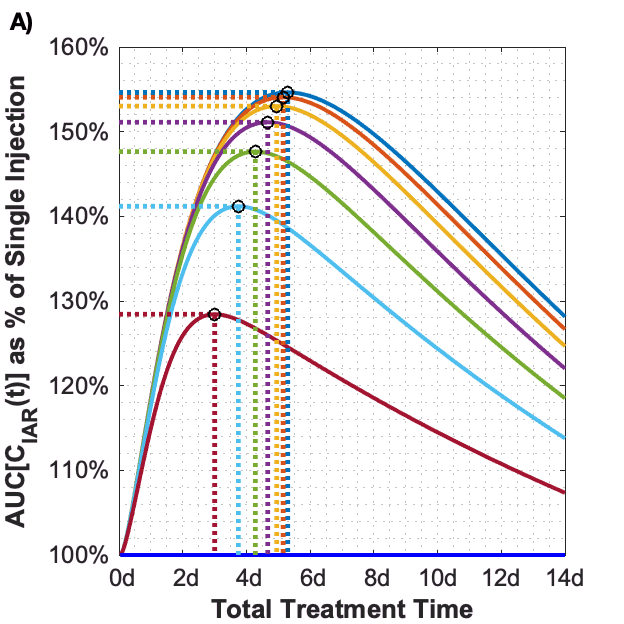

%figure;
%scatter(trt_cts_grid(:), trt_times_grid(:), 1, [0 0 0]);
%xticks(treatment_cts)
%hold on;
%contour(trt_cts_grid, trt_times_grid, ys(:,:,1))
%title('Contour Plot of AUC[C_{IAR}] per R0');
%xlabel('# of Treatments'); ylabel('Total Length of Treatment (hrs)');
%hold on;
%colorbar;

%figure;
%bar3(ys(:,:,1));
%xticks(treatment_cts)
%xlabel('# of Treatments'); ylabel('Total Length of Treatment (hrs)');
%yticks(treatment_times);
%set(gca,'YTickLabel',treatment_times(2:2:end));

set(gcf, 'DefaultAxesColorOrder', cols ); % I don't think this actually does anything
figure; hold on; box on; grid minor;
%if you want to convert it to time between injections instead of
%the overall times of treatment, then for time value, use:
%ones(1,7)./fliplr(treatment_cts) .* treatment_times'
y=fliplr(100*ys(:,:,1)./ys(:,1,1));
%plot( treatment_times', y, 'LineWidth', plotlinew );
plot( treatment_times', y(:,1:end-1), 'LineWidth', plotlinew );
plot( treatment_times', y(:,end),'b', 'LineWidth', plotlinew);
xlim([0 Inf]); ylim([100 156]);

if any(plotMax)
    maxVals = 100*optim_AUC_cIAR(:,2,2)./ys(1,1,1);
    maxValTimes = optim_AUC_cIAR(:,1,2);
    for it=(length(y(1,:))-1):-1:1
        yi=y(:,end-it);
        yl = get(gca,'Ylim'); xl = get(gca,'Xlim');
        maxvaltime = maxValTimes(it+1);
        maxval = maxVals(it+1);
        if plotMax(it+1)
            plot([xl(1) maxvaltime maxvaltime+eps],[maxval maxval, yl(1)],':','LineWidth',plotlinew*1.2);
        else
            plot([maxvaltime maxvaltime+eps maxvaltime+(maxvaltime-xl(1))*0.25],[yl(1) maxval maxval],':','LineWidth',plotlinew*1.2);
            text(maxvaltime+(maxvaltime-xl(1))*0.25,maxval, {num2str(maxval,'%.2f%%')})
        end
        plot(maxvaltime, maxval,'ko')
    end
    %yticks([100;maxVals(plotMax==1)]);
    %set(gca,'yticklabel',num2str(get(gca,'ytick')','%.1f%%'));
    
    ylim([100 160]);
    set(gca,'yticklabel',num2str(get(gca,'ytick')','%.0f%%'));
else
    set(gca,'yticklabel',num2str(get(gca,'ytick')','%.0f%%'));
end

xticks(0:2:14);
set(gca,'xticklabel',num2str(get(gca,'xtick')','%.0fd'));
if showtitles
    title('Effects of Scheduling on Bound Antibody Levels, AUC[C_{IAR}]');
end
xlabel('Total Treatment Time','FontWeight','bold'); xlim([0 Inf]);
ylabel('AUC[C_{IAR}(t)] as % of Single Injection', 'FontWeight','bold');
%{} needed in strcat for whitespace trimming
legend([strcat({''}, num2str(fliplr(treatment_cts(2:end))'),' Injections'); '1 Injection'],'Location','northeast')

%Add A), B), C) etc text here
letter='A';
xloc=0; yloc = 1;
if (yloc >= 0) && (yloc <= 1) && (xloc >= 0) && (xloc <= 1) %otherwise will throw error
    %Letter should be in 12pt helvetica font, regardless of the font of the rest of the figures, per JNM
    annotation('textbox', [xloc, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',12,'fontname','helvetica', 'FontWeight', 'bold','tag','FigurePartLetter');
end

legend('hide'); %we'll present the legend separately
%set(gca,'LineWidth',axislinewidth*resratio); %don't do this so that the grids aren't too thick
set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 11 11]); %for saving the file
set(gcf,'Units','centimeters','Position', [0 0 11 11]); %for showing up in the mlx file
print(['Figures/Scheduling/SchedulingOnAUC_IAR'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Scheduling/SchedulingOnAUC_IAR'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI
print(['Figures/Scheduling/SchedulingOnAUC_IAR 300p'], '-dtiff', '-r300'); %<-Save as TIFF with certain DPI

Therapeutic index

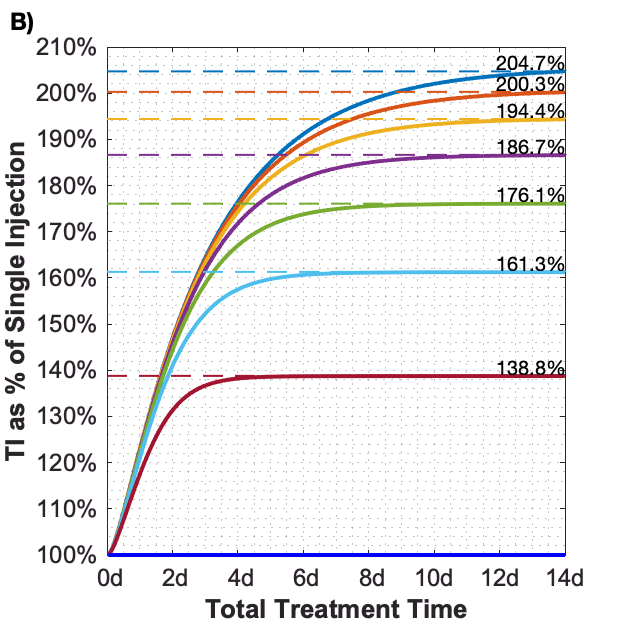

figure; hold on; box on; grid minor;
set(gcf, 'DefaultAxesColorOrder', cols); % I don't think this actually does anything
y=fliplr(100*ys(:,:,3)./ys(:,1,3));
%plot(treatment_times',y,'LineWidth',plotlinew);
plot(treatment_times',y(:,1:end-1),'LineWidth',plotlinew);
plot(treatment_times',y(:,end),'b','LineWidth',plotlinew);
xlim([0 Inf]); ylim([100 210]);

if any(plotMax)
    [maxVals, maxValTimes] = max(y); %get the max of each col (each dose)
    for it=1:(length(y(1,:))-1) %opposite dir as other plots
        yi=y(:,end-it);
        yl = get(gca,'Ylim'); xl = get(gca,'Xlim');
        if xl(2)==inf, xl(2)=max(treatment_times); end
        maxval = maxVals(it);
        maxvaltime = maxValTimes(it);
        plot(xl,[maxval maxval],'--','LineWidth',plotlinew*0.5);
        text(max(xl)*0.85,maxval+2, {num2str(maxval,'%.1f%%')}) %righthand
        %text(size(y,2)-1-it, maxval+2, {num2str(maxval,'%.1f%%')}) %lefthand curved
    end
    %don't need to add 100 because already there
    %yticks(fliplr(maxVals));
    %set(gca,'yticklabel',num2str(get(gca,'ytick')','%.1f%%'));
    
    yticks(100:10:220);
    set(gca,'yticklabel',num2str(get(gca,'ytick')','%.0f%%'));
    
    
else
    set(gca,'yticklabel',num2str(get(gca,'ytick')','%.0f%%'));
end

xticks(0:2:14);
set(gca,'xticklabel',num2str(get(gca,'xtick')','%.0fd'));

l=legend([strcat({''}, num2str(fliplr(treatment_cts(2:end))'),' Injections'); '1 Injection'],...
    'Location','best','FontSize',8);
xlabel('Total Treatment Time', 'FontWeight','bold'); xlim([0 Inf]);
ylabel('TI as % of Single Injection', 'FontWeight','bold');
if showtitles
    title('Effects of Scheduling on Therapeutic Index');
end

%Add A), B), C) etc text here
letter='B';
xloc=0; yloc = 1;
if (yloc >= 0) && (yloc <= 1) && (xloc >= 0) && (xloc <= 1) %otherwise will throw error
    %Letter should be in 12pt helvetica font, regardless of the font of the rest of the figures, per JNM
    annotation('textbox', [xloc, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',12,'fontname','helvetica', 'FontWeight', 'bold','tag','FigurePartLetter');
end

legend('hide'); %we'll present the legend separately
%set(gca,'LineWidth',axislinewidth*resratio); %don't do this so that the grids aren't too thick
set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 11 11]); %for saving the file
set(gcf,'Units','centimeters','Position', [0 0 11 11]); %for showing up in the mlx file
print(['Figures/Scheduling/SchedulingOnTI'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Scheduling/SchedulingOnTI'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI
print(['Figures/Scheduling/SchedulingOnTI 300p'], '-dtiff', '-r300'); %<-Save as TIFF with certain DPI

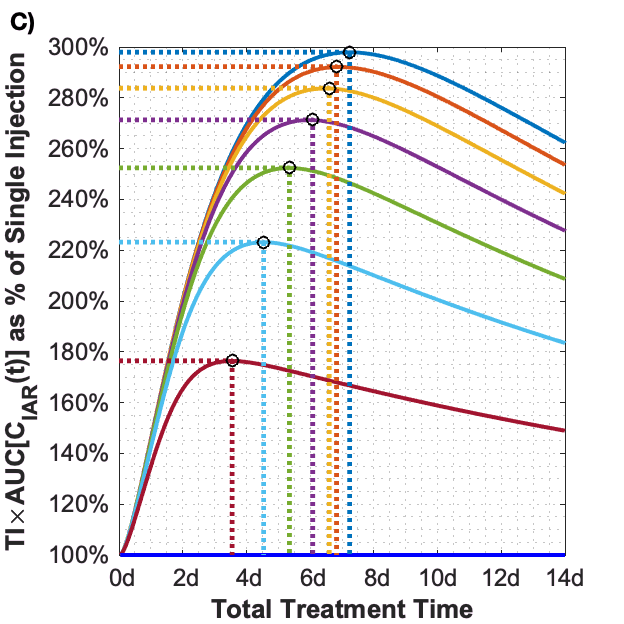

figure; hold on; box on; grid minor;
set(gcf, 'DefaultAxesColorOrder', cols);
y=fliplr(100*( ys(:,:,3).*ys(:,:,1) ))./( ys(:,1,3).*ys(:,1,1) );
%plot(treatment_times',y,'LineWidth',plotlinew);
plot(treatment_times',y(:,1:end-1),'LineWidth',plotlinew);
plot(treatment_times',y(:,end),'b','LineWidth',plotlinew);
xlim([0 Inf]); ylim([100 300]);

if any(plotMax)
    %index 5 for TP, 1 for AUC_cIAR.
    %Since all elements are same in 1 injection ys(:,1,1) just use ind 1
    %Use the graphically calculated max, not the fminbnd because its time values were found to be more precise (it was okay for AUC[C_IAR] though)
    maxVals = 100*optim_TP_est(:,5,2)./( ys(1,1,3).*ys(1,1,1) );
    maxValTimes = optim_TP_est(:,1,2);
    for it=(length(y(1,:))-1):-1:1
        yi=y(:,end-it);
        yl = get(gca,'Ylim'); xl = get(gca,'Xlim');
        maxvaltime = maxValTimes(it+1);
        maxval = maxVals(it+1);
        if plotMax(it+1)
            plot([xl(1) maxvaltime maxvaltime+eps],[maxval maxval, yl(1)],':','LineWidth',plotlinew*1.2);
        else
            plot([maxvaltime maxvaltime+eps maxvaltime+(maxvaltime-xl(1))*0.25],[yl(1) maxval maxval],':','LineWidth',plotlinew*1.2);
            text(maxvaltime+(maxvaltime-xl(1))*0.25,maxval, {num2str(maxval,'%.2f%%')})
        end
        
        plot(maxvaltime, maxval,'ko')
    end
    %yticks([100;maxVals(2:end)]);
    %set(gca,'yticklabel',num2str(get(gca,'ytick')','%.1f%%'));
    
    set(gca,'yticklabel',num2str(get(gca,'ytick')','%.0f%%'));
    
else
    set(gca,'yticklabel',num2str(get(gca,'ytick')','%.0f%%'));
end

xticks(0:2:14);
set(gca,'xticklabel',num2str(get(gca,'xtick')','%.0fd'));
if showtitles
    title('Effects of Scheduling on AUC[C_{IAR}] \times Therapeutic Index');
end
xlabel('Total Treatment Time','FontWeight','bold'); xlim([0 Inf]);
ylabel('TI\timesAUC[C_{IAR}(t)] as % of Single Injection','FontWeight','bold');
legend([strcat({''}, num2str(fliplr(treatment_cts(2:end))'),' Injections'); '1 Injection'],'Location','northwest','FontSize',12)

%Add A), B), C) etc text here
letter='C';
xloc=0; yloc = 1;
if (yloc >= 0) && (yloc <= 1) && (xloc >= 0) && (xloc <= 1) %otherwise will throw error
    %Letter should be in 12pt helvetica font, regardless of the font of the rest of the figures, per JNM
    annotation('textbox', [xloc, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',12,'fontname','helvetica', 'FontWeight', 'bold','tag','FigurePartLetter');
end

legend('hide'); %we'll present the legend separately
%set(gca,'LineWidth',axislinewidth*resratio); %don't do this so that the grids aren't too thick
set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 11 11]); %for saving the file
set(gcf,'Units','centimeters','Position', [0 0 11 11]); %for showing up in the mlx file
print(['Figures/Scheduling/SchedulingOnTP'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Scheduling/SchedulingOnTP'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI
print(['Figures/Scheduling/SchedulingOnTP 300p'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI

Do this after making the figure to get the legend only

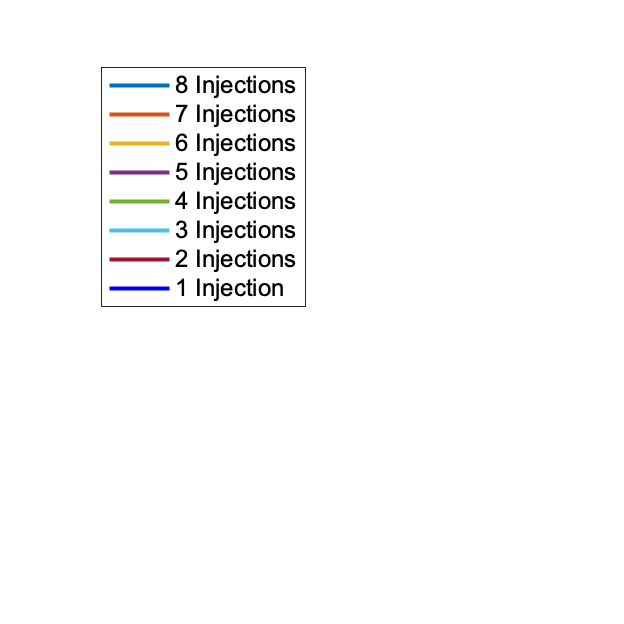

delete(findall(gcf,'Tag','FigurePartLetter'))
legend('show');
xlim([-1000 -999]);
%set(plots, 'visible', 'off');
set(gca, 'visible', 'off');

print(['Figures/Scheduling/SchedulingLegend'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Scheduling/SchedulingLegend'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI
print(['Figures/Scheduling/SchedulingLegend 300p'], '-dtiff', '-r300'); %<-Save as TIFF with certain DPI

function [opt, AUC_cIAR, AUC_cIA, therapind, therapprod]=solveWithSchedule(...
    treatment_ct, opt_val, total_treatment_time, activityAdmin, Vv, CL, defined_params)
%total_treatment_time is in units of days
%activityAdmin in mCi
%Vv in L
%CL in L/s

if total_treatment_time <= 0
    AUC_cIAR=0;
    AUC_cIA=1;
    therapind=0;
    therapprod=0;
else
    infusion_times = linspace(0,total_treatment_time,treatment_ct+1);
    infusion_times = infusion_times(1:end-1);
    time_values_needed3 = [0:1:((total_treatment_time+4)*1440)]*60;
    activityAdminPerInj = activityAdmin*ones(1,treatment_ct)/treatment_ct;
    [tspl, cIobsspl, AUC_cIAR, AUC_cIA, ~] = solveModelMultInfus(...
        infusion_times*3600*24, activityAdminPerInj,...
        Vv, CL, time_values_needed3, defined_params);
    therapind = AUC_cIAR/AUC_cIA;
    therapprod = therapind * AUC_cIAR;
end


if opt_val == 1
    opt = AUC_cIAR;
elseif opt_val == 2
    opt = AUC_cIA;
elseif opt_val == 3
    opt = therapind;
elseif opt_val == 4
    opt = therapprod;
end
end
